A = [1 0; 0 -1], B = [1 2]', syms k1 k2 s, K = [k1 k2]

A =      1     0
     0    -1


B =      1
     2


$$K = \left(\begin{array}{cc} k_{1} & k_{2} \end{array}\right)$$

A+B*K

$$ans = \left(\begin{array}{cc} k_{1}+1 & k_{2}\\ 2\,k_{1} & 2\,k_{2}-1 \end{array}\right)$$

det(s*eye(2)-ans)

$$ans = 2\,k_{2}-k_{1}-k_{1}\,s-2\,k_{2}\,s+s^{2}-1$$



K = -place(A,B,[-4 -5]*2)

K =   -49.5000   15.7500




IC  = rand(1,2)

IC =     0.1576    0.9706


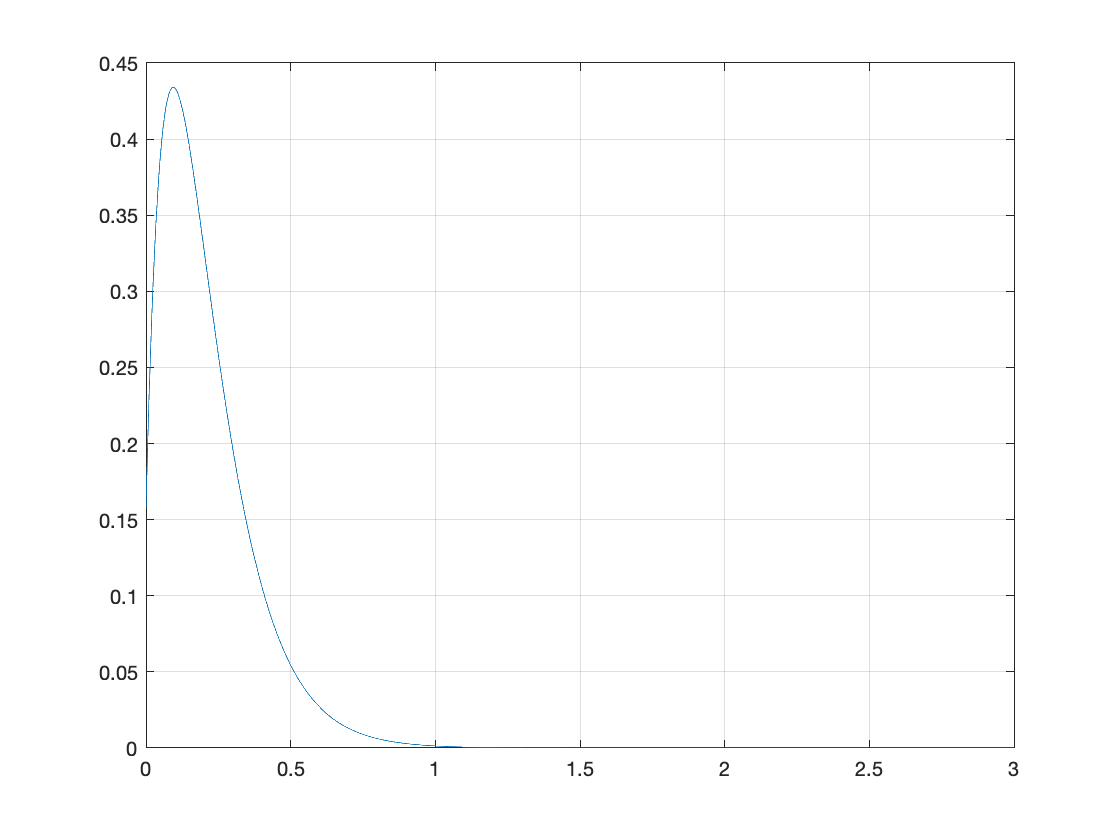

tmax = 3;
t = linspace(0,tmax,2^12);
[t,x] = ode45(@(t,x) xfun_SF(x,A,B,K,t),t,IC); % linear

plot(t,x(:,1))
grid on

function dxdt = xfun_SF(x,A,B,K,t)
dxdt = (A+B*K)*x;
end